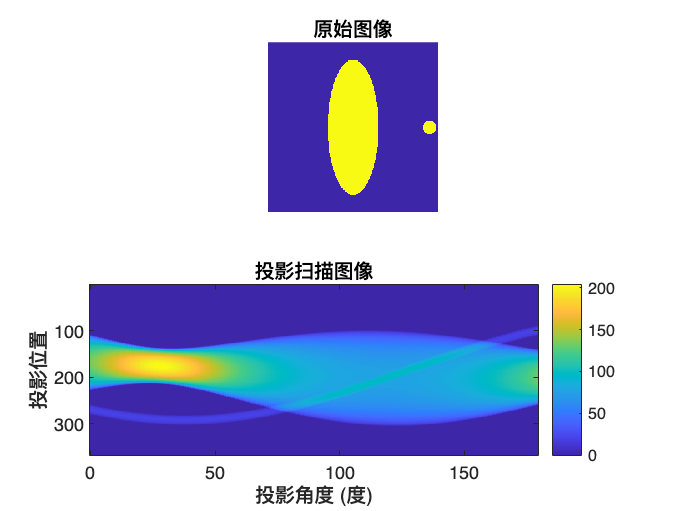

% 读取或生成原始图像
I = File1;

% 平移图像，使得旋转中心与图像中心对齐
translation = [estimated_center_x, estimated_center_y] - size(I) / 2;
tform = affine2d([1 0 0; 0 1 0; translation(1) translation(2) 1]);
I_translated = imwarp(I, tform, 'OutputView', imref2d(size(I)));

% 旋转图像，使得初始角度为 0
I_rotated = imrotate(I_translated, -estimated_initial_angle, 'bilinear', 'crop');

% 定义投影角度
theta = 0:179;

% 计算 Radon 变换，生成投影扫描图像
R = radon(I_rotated, theta);

% 显示原始图像和投影扫描图像
figure;
subplot(2, 1, 1);
imshow(I, []);
title('原始图像');

subplot(2, 1, 2);
imagesc(theta, 1:size(R, 1), R);
colormap(gray);
colorbar;
xlabel('投影角度 (度)');
ylabel('投影位置');
title('投影扫描图像');
colormap("parula")